mtrue = [0.18 16.21 9.81]' %true m

mtrue =     0.1800
   16.2100
    9.8100


m = 20; %rows
n = 3;  %columns

tj = linspace(0,3,m) %temporal domain

tj =          0    0.1579    0.3158    0.4737    0.6316    0.7895    0.9474    1.1053    1.2632    1.4211    1.5789    1.7368    1.8947    2.0526    2.2105    2.3684    2.5263    2.6842    2.8421    3.0000


### N0.2 a)

#### (i). Form G

%forming G matrix
G = zeros(m,n); %m by n container

for i = 1:n
    for j = 1:m
       G(j,1) = 1;
       G(j,2) = tj(j);
       G(j,3) = -0.5*tj(j)^2;
    end
end 
disp(G)

    1.0000         0         0
    1.0000    0.1579   -0.0125
    1.0000    0.3158   -0.0499
    1.0000    0.4737   -0.1122
    1.0000    0.6316   -0.1994
    1.0000    0.7895   -0.3116
    1.0000    0.9474   -0.4488
    1.0000    1.1053   -0.6108
    1.0000    1.2632   -0.7978
    1.0000    1.4211   -1.0097
    1.0000    1.5789   -1.2465
    1.0000    1.7368   -1.5083
    1.0000    1.8947   -1.7950
    1.0000    2.0526   -2.1066
    1.0000    2.2105   -2.4432
    1.0000    2.3684   -2.8047
    1.0000    2.5263   -3.1911
    1.0000    2.6842   -3.6025
    1.0000    2.8421   -4.0388
    1.0000    3.0000   -4.5000



### (ii). Form dtrue

dtrue =  G*mtrue;
disp(dtrue)

    0.1800
    2.6172
    4.8098
    6.7579
    8.4613
    9.9202
   11.1346
   12.1043
   12.8295
   13.3102
   13.5462
   13.5377
   13.2846
   12.7869
   12.0447
   11.0579
    9.8265
    8.3506
    6.6301
    4.6650



#### (iii). Form noisy data d

mean  = 0;
std = 2;

%noise
noise = 2*randn(m,1);

%noise data
d = dtrue + noise;
disp(d)

   -0.8346
    3.0888
    5.3014
    6.8979
    7.2442
    7.4750
   11.7676
    9.4186
   10.7652
   15.9726
   12.7084
   13.2570
   15.0842
   12.1867
   14.1034
   10.3678
   11.8521
    9.6093
    6.2041
    2.9336



### Plot dtrue and d as points on the same graph

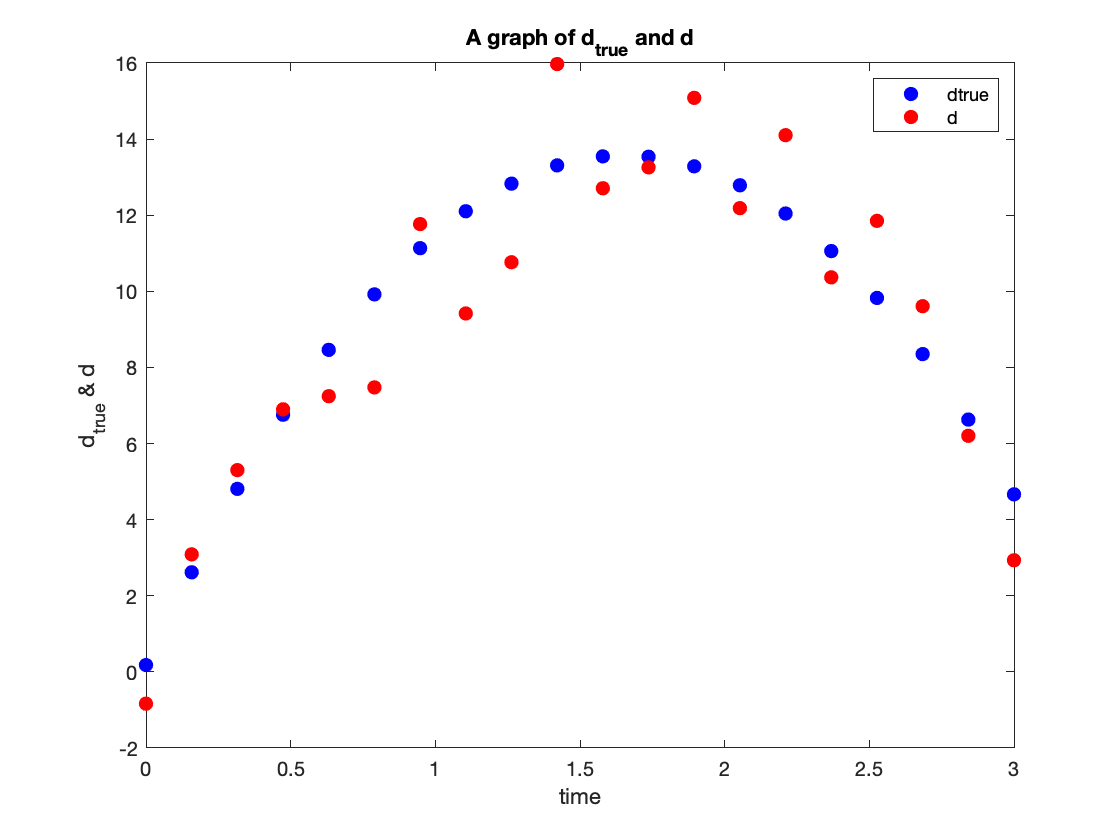

figure(1)
plot(tj,dtrue,'b.','MarkerSize',20)
hold on
plot(tj,d,'r.','MarkerSize',20)
title('A graph of d_{true} and d')
legend('dtrue','d')
xlabel('time'); 
ylabel('d_{true} & d')

### Discuss the difference between the data

Comparing the trud data, dtrue, (blue)  and the noisy data, d, (red), its clearly shown d has alot of dispersed data points due to the effect of noise while dtrue is a smooth curve without any disturbances. Even though the noisy data is distorted it will still depicts the trend of the true data.

## N0.2 b)

### Solve Gm = d for m and plot y(t) using m and mtrue

m = G\d

m =    -0.5939
   16.8718
   10.0318


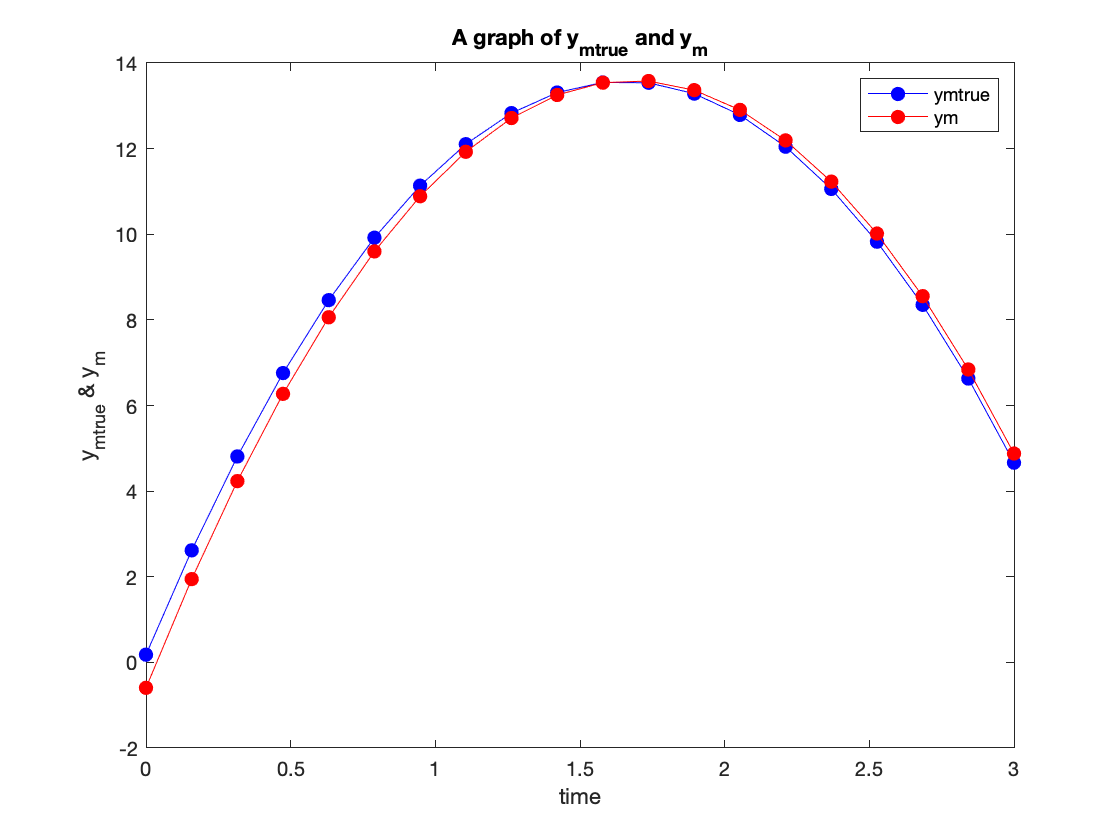

%function
y = @(t,m1,m2,m3) m1 + m2*t - 0.5*m3*t.^2;

%using mtrue
ymtrue = y(tj, mtrue(1),  mtrue(2), mtrue(3));
%using m
ym = y(tj, m(1),  m(2), m(3));

%plot y
figure(2)
plot(tj,ymtrue,'b.-','MarkerSize',20)
hold on
plot(tj, ym,'r.-','MarkerSize',20)
title('A graph of y_{mtrue} and y_{m}')
legend('ymtrue','ym')
xlabel('time'); 
ylabel('y_{mtrue} & y_{m}')

### Discuss the difference between the trajectories.

There is a discrepancy between the trajectories: ymtrue (blue) and ym (red)  obtained using mtrue and m values respectively. This is due to the noisy data ,d, used to obtain m and the forward model (y(t)) used to obtain y which is approximate, hence even the trajectory wont fit the the observed trajectory (ytrue) due to the distorted values of m. Therefore for what ever values of the m, the trajectories will never fit each other but will always have the same trend.